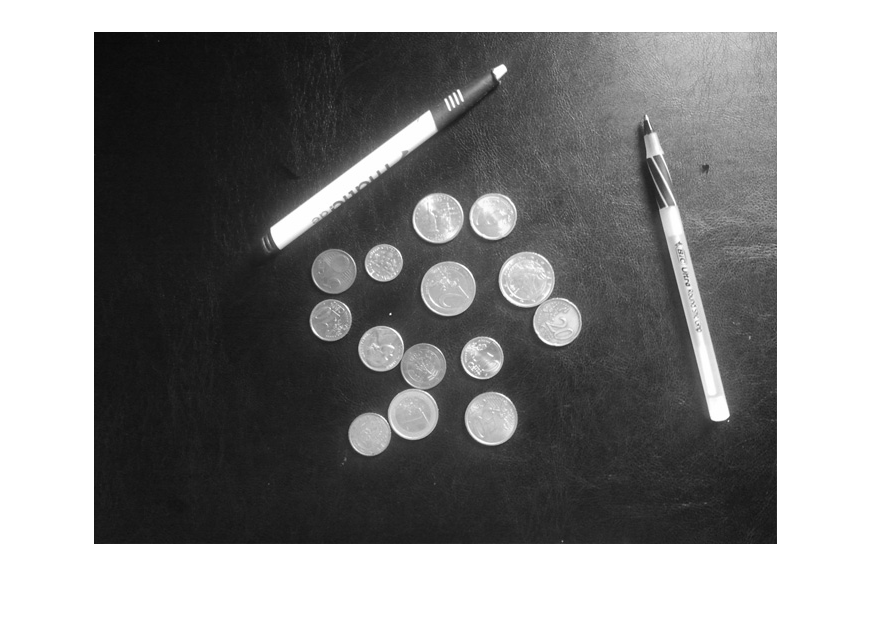

img = rgb2gray(imread("input/ps1-input1.png"));
imshow(img);

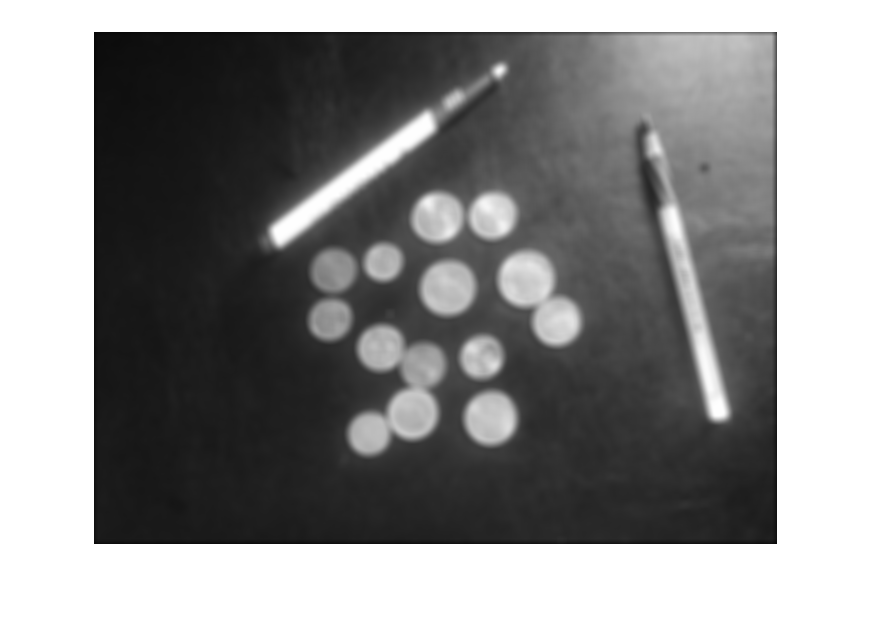

filter = fspecial('gaussian', 10, 4);
img_smooth = imfilter(img, filter);
imshow(img_smooth);

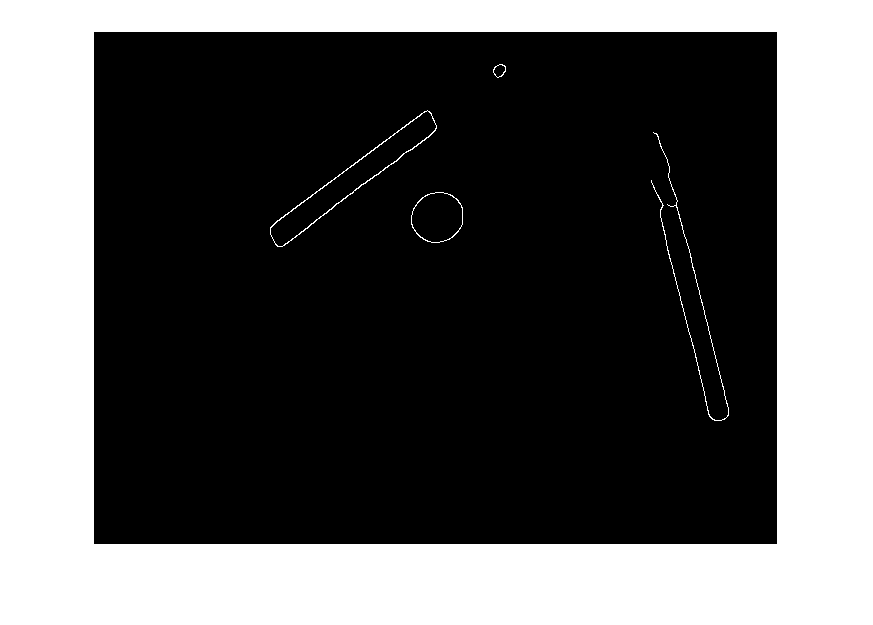

img_smooth_edges = edge(img_smooth,'Canny',[0.2 0.9] ,'both' );
imshow(img_smooth_edges);

img_edges = img_smooth_edges;

maxd = ceil(sqrt(size(img_edges,1)^2 + size(img_edges,2)^2));

deg_bins = linspace(-90,90,181);
d_bins = linspace(-maxd, maxd, maxd+1);
H = zeros(length(d_bins),length(deg_bins));
for r= 1: size(img_edges,1)
    for c= 1: size(img_edges,2)  
        if img_edges(r,c) == 1 
          for deg = -90 : 90
            x=c; y=r;
            angle = deg*pi/180;
            d = ceil(x*cos(angle)+y*sin(angle));
            deg_i = findbin(deg_bins, deg);
            d_i = findbin(d_bins, d);
            H(d_i,deg_i) = H(d_i,deg_i) +  1; 
          end
       end
    end
end


% hthresh = H>0;
% imshow(hthresh,[]);
imshow(H,[]);
maxH = max(H(:))

maxH = 239

[maxrowyi , maxcolxi] = find(H >= 0.7*maxH & H<=maxH);

a = [maxcolxi,maxrowyi]

a =     77   681
    77   691
   144   560
   144   571
   145   559



marks_image = insertMarker(H, a)

marks_image = marks_image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

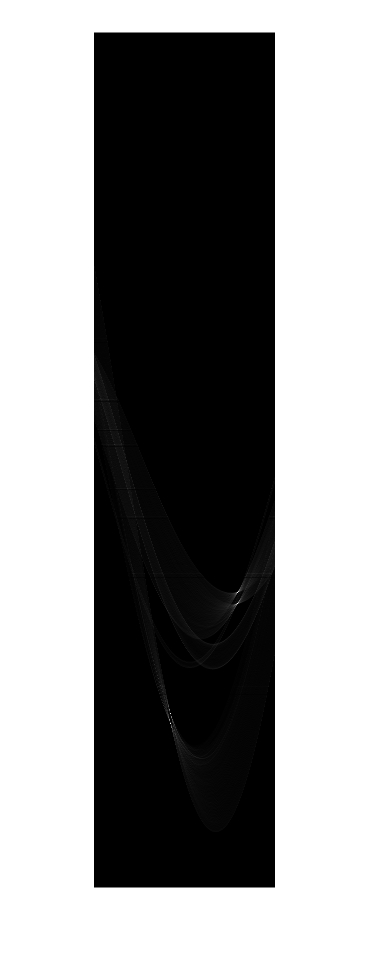

colormap gray;

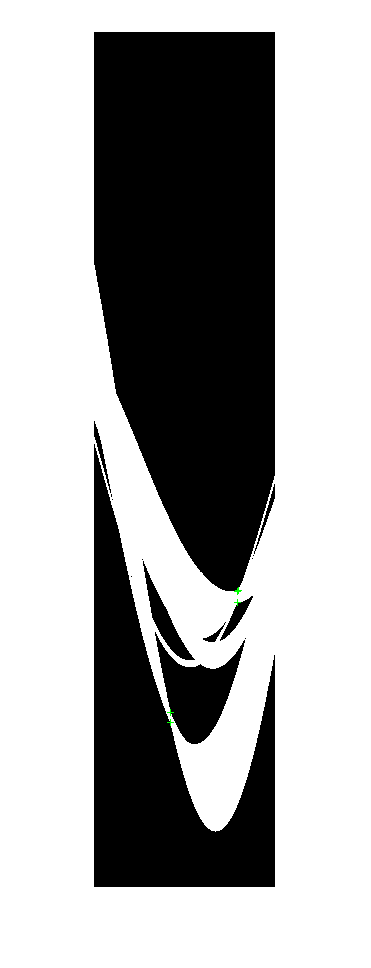

imshow(marks_image,[])

x = 1 : size(img_edges,2);
size(a,1)

ans = 5

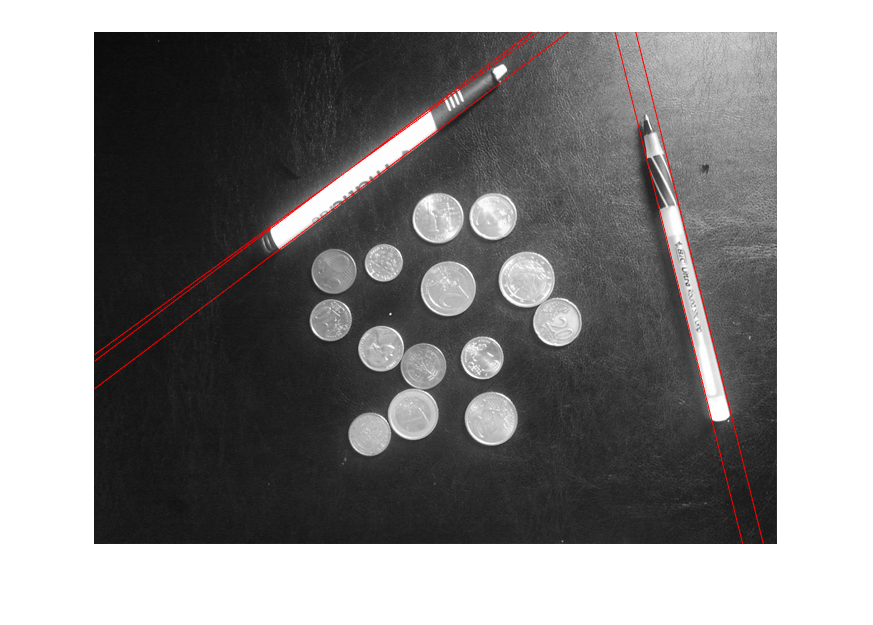

************line1


dvalue = 506

tvalue = -0.2443

other line


************line2


dvalue = 526

tvalue = -0.2443

other line


************line3


dvalue = 264

tvalue = 0.9250

other line


************line4


dvalue = 286

tvalue = 0.9250

other line


************line5


dvalue = 262

tvalue = 0.9425

other line


imshow(img)
for i = 1:size(a,1)
    disp("************line"+i);
    dvalue = d_bins(1, a(i,2))
    tvalue = deg_bins(1,a(i,1))*pi/180
    if (tvalue == 0)
        disp("inf line");
        line([dvalue dvalue],[1 size(img_edges,2)], 'color', 'r')
    else
        disp("other line");
        line(x,(dvalue-x*cos(tvalue))/sin(tvalue), 'color','r')
    end
end